# **T2N Tutorial**

**This script is to show you some applications of t2n. Tutorial A and B initialize the morphology and standard parameters (and need thus be run at least once before starting one of the other tutorials), whereas the other sections define the different simulations.**

Note: T2N requires NEURON and TREES to be installed! See Documentation for further information.

Note for Mac users: Matlab has to be run from a Terminal for T2N to work properly.

## Tutorial A - initialize parameters and the neuron structure

First we need to be sure that Matlab finds all necessary files located in the T2N and TREES folder. 

if ~exist('t2n','file')         % checks if T2N is not already on the Matlab path
    if exist('t2n_Tutorial.mlx','file')  % probably you are in the t2n/Tutorials folder
        addpath(genpath(fileparts(pwd)));
    else
        error('Please run the "t2n_runthisAfterUnzip.m" script in the T2N folder or add the T2N folder including subfolders to the Matlab path!')
    end
end
if ~exist('load_tree','file')
    error('Please run the "start_trees.m" script in the TREES folder or add that folder including subfolders to the Matlab path!')
end

Now we need to initialize the t2n parameter structure which includes general NEURON settings. Most of these settings are set to a default value if not explicitly set, but you might want to control most of them

t2n_initModelfolders(pwd);                                  % initialize model folder hierarchy in current folder

vecevent.mod copied to lib_mech folder
non-existent folder lib_genroutines created
fixnseg.hoc copied to model folder
genroutines.hoc copied to model folder
pasroutines.hoc copied to model folder
Please put your morphologies (.swc, .mtr, .neu etc.) into the "morphos" folder
Please put mod files into the "lib_mech" folder
Please put custom code (if needed) into the "lib_custom" folder and define with "neuron.custom" (see Documentation)



neuron = [];                                                % clear neuron structure
neuron.params.v_init = -80;                                 % starting membrane potential [mV] of all cells
neuron.params.dt = 0.025;                                   % integration time step [ms]
neuron.params.tstop = 300;                                  % stop simulation after this (simulation) time [ms]
neuron.params.prerun = -400;                                % add a pre runtime [ms] to let system settle
neuron.params.celsius = 10;                                 % temperature [celsius]
neuron.params.nseg = 'dlambda';                             % the dlambda rule is used to set the amount of segments per section. Alternatively, a fixed number can be entered or a string 'EachX' with X being the interval between segments [micron]
neuron.params.accuracy = 0;                                 % optional argument if number of segments should be increased in the soma and axon


Now we set the t2n neuron structure which defines all mechanisms, point processes, synapses, connections recordings, protocols etc. that should be used in the simulation. The mechanisms and point processes can be any that is defined in the standard NEURON environment or that has been  written as .mod file and saved to the 'lib_mech' folder in the model folder from which it can be compiled by t2n. 'neuron' is a Matlab structure  if a single simulation should be run.


neuron.experiment = 'test';                                                 % give your simulation run a name (necessary when using advanced t2n protocols)
for t = 1                                                                   % preconfiguration to loop through several morphologies, now only one morphology is considered
    neuron.mech{t}.all.pas = struct('g',0.0003,'Ra',100,'e',-80,'cm',1);    % add passive channel to all regions and define membrane capacity [µF/cm²], cytoplasmic resistivity [Ohm cm] and e_leak [mV]
    neuron.mech{t}.soma.pas = struct('g',0.0004,'Ra',100,'e',-80,'cm',1);    % add passive channel to somatic regions (will overwrite the "all" definition) and define membrane capacity [µF/cm²], cytoplasmic resistivity [Ohm cm] and e_leak [mV]
    % alternatively to the compact code above, one can define each
    % parameter line by line as with NEURON by writing:
    % neuron.mech{t}.all.pas.g = 0.0003;
    % neuron.mech{t}.all.pas.Ra = 100;
    % neuron.mech{t}.all.pas.e = -80;
    % neuron.mech{t}.all.pas.cm = 1;
    neuron.mech{t}.all.k_ion.ek = -90;
    neuron.mech{t}.all.na_ion.ena = 50;
    neuron.mech{t}.soma.hh = struct('gnabar',0.25,'gkbar',0.036,'gl',0);     % add Hodgkin-Huxley Sodium channel only to soma
    neuron.record{t}.cell = struct('node',1,'record','v');                   % record voltage "v" from first node (i.e. the soma)
end

## Tutorial B - loading a morphology

First we need a morphology (tree), on which we can add the channels etc. We are using here a sample_tree from the TREES toolbox which loads a small tree. You can also load a different tree by using "tree = load_tree;", or load another example, e.g. "tree = {hsn_tree};"

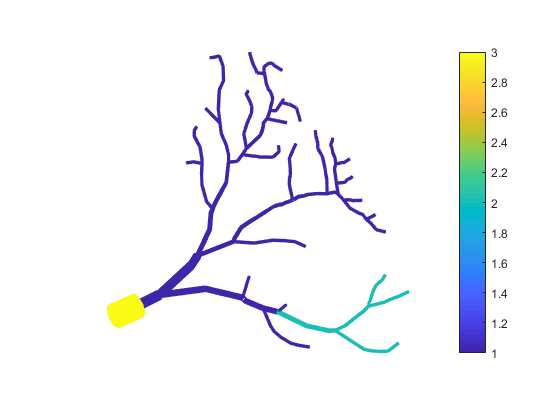

tree = {sample_tree};   % load sample tree
% this tree has no soma region yet, so it is perfectly suitable to show you
% how new regions can be defined in TREES toolbox. 
% just make the first two nodes from the root "somatic"
tree{1}.R(1:2) = 3;     % make the first two nodes a new region
tree{1}.rnames{3} = 'soma';   % name the region "soma"
tree{1}.D(1:2) = 10;        % increase diameter of the somatic nodes

figure;plot_tree(tree{1},tree{1}.R);colorbar   % plot tree with region code
axis off


tree = tree(1);                                                              % for simplicity, only one tree is looked at (if several exist at all)
tree = t2n_writeTrees(tree,[],fullfile(pwd,'test.mtr'));                 % transform tree to NEURON morphology (.hoc file). This only has to be done once for each morphology

Tree hoc writing time: 0 min 2.12 sec


## Tutorial C - simulation protocol: somatic current injection

Now we want to do a simple somatic current injection, execute neuron and plot the result. By copying the 'neuron' structure into a new variable 'nneuron' and modify only this one in each protocol, we do not have to rerun the upper sections each time,

nneuron = neuron;                                                           % copy standard neuron structure

% now we define a 100 ms current injection of 0.6 nA that is started at 
% time point 50 ms
nneuron.pp{1}.IClamp = struct('node',1,'times',[50 150],'amp',[0.6 0]);     % add a current clamp electrode to the first node and define stimulation times [ms] and amplitudes [nA]
nneuron.record{1}.IClamp = struct('node',1,'record','i');                   % record the current of the IClamp just for visualization

out = t2n(nneuron,tree,'-w-q');                                      % execute t2n and receive output

nrnmech.dll compiled from mod files in folder lib_mech


nrnmech.dll successfully renamed in nrnmech.dll ... and .o/.c files deleted


After execution of t2n we can plot the results. T2N returns all recordings that had previously been defined. We can access them in out.record{1} where {1} accesses the recordings of the first tree/morphology. Subsequently all recordings of distributed mechanisms or other cell-specific parameters (e.g. voltage) can be found in the field  'cell', whereas recorded values from point processes can be found under the name of that process (e.g. 'IClamp'). Following that comes the name of the recorded variable and the index to the node at which the variable has been recorded or the corresponding point process had been placed  (e.g. v{1} for the voltage at the first node). The time vector can be found in out.t and fits to all recordings, except if the options params.local_dt has been used which allows NEURON to use different time steps for different trees. In that case out.t is a cell array of vectors.

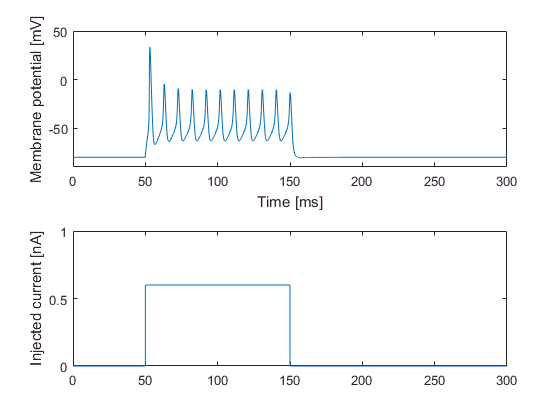

figure; 
subplot(2,1,1)                                                              % make a subplot in the figure
plot(out.t,out.record{1}.cell.v{1})                                         % plot recorded somatic voltage (time vs voltage)
ylim([-90,50])
xlim([0,nneuron.params.tstop])
ylabel('Membrane potential [mV]')
xlabel('Time [ms]')
subplot(2,1,2)                                                              % make another subplot in the figure
plot(out.t,out.record{1}.IClamp.i{1})                                       % plot electrode current (time vs current)
ylim([0,1])
xlim([0,nneuron.params.tstop])
ylabel('Injected current [nA]')

## Tutorial D - simulation protocol: several simulations with different injected current amplitudes (f-I relationship)

Now we learn something about the real strength of t2n: It can execute simulations in parallel! All we have have to do is to create a cell array of neuron structures (each defining a different protocol) and hand them to t2n. Here we use this to simulate different current injections, but in principle this can be used for any different protocols (e.g. different channels, different synapses, different stimulation patterns etc).

amp = 0:0.12:0.6;                  % define a series of amplitudes for the electrode (here: 6 steps from 0 to 0.6 nA)
nneuron = cell(numel(amp),1);      % initialize (clear) simulation list

 Principally, we could copy the standard neuron structure into the neuron cell array for each protocol and then add the IClamp with different amplitude which would look like this: 

% for n = 1:numel(amp)
%     nneuron{n} = neuron;                                                            % use neuron structure defined above as basis
%     nneuron{n}.pp{1}.IClamp = struct('node',1,'times',[50 150],'amp',[amp(n) 0]);   % only define what is changed in for the next simulations
% end

However, in this case T2N would translate the complete descriptions of all mechanisms etc into hoc code for each simulation. This might be no big deal when defining only 6 simulations, but could be very time and (to lesser extent) disk space consuming when defining hundreds of  simulations. Hence, it is recommended to use the t2n_as function which tells t2n to simply reuse the hoc file of a specific simulation instance for all definitions that have not been defined in the other simulations. Here is how it is used:

nneuron{1} = neuron;                                                               % use neuron structure defined above as basis for the first simulation instance
for n = 1:numel(amp)
    nneuron{n}.pp{1}.IClamp = struct('node',1,'times',[50 150],'amp',[amp(n) 0]);   % now define the IClamp in all simulations (remember that all other parameters were only defined in simulation 1) and...
end
nneuron = t2n_as(1,nneuron);                                                        % ... use the previously defined neuron structure as basis for each other simulation

Now T2N only writes hoc code for initialization of the IClamp point  process in each simulation and uses the hoc code about morphology,  recordings and mechanisms from the first simulation

out = t2n(nneuron,tree,'-w-q');                                              % execute t2n

Now we can plot the recorded somatic voltages for each current step

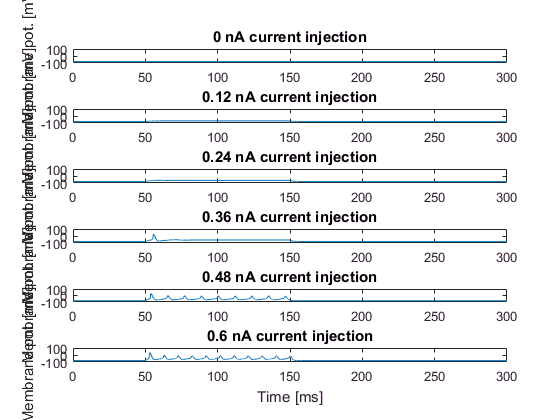

figure; hold all
for n = 1:numel(amp)                                    % go through simulations/amplitudes
    subplot(numel(amp),1,n)                             % make subplot for each simulation
    plot(out{n}.t,out{n}.record{1}.cell.v{1})           % plot time vs voltage of current simulation
    title(sprintf('%g nA current injection',amp(n)))    % add legend
    ylabel('Membrane pot. [mV]')
end
linkaxes                                                % make all axes the same size
xlabel('Time [ms]')

Using a "findpeaks" on the voltage vectors and plotting it against the amp vector would give us a so called f-i-relationship. However, we can save a lot of typing/formatting, if we use the the t2n functions for running current steps and plotting an f-i-relationship:

ostruct.amp = 0:0.12:0.6;         % specify the same current steps [nA] as above
ostruct.delay = 50;               % specify the same injection onset [ms] as above
ostruct.duration = 100;           % specify the same injection duration [ms] as above
mkdir('tmpfolder')                % t2n_currSteps saves the result of the simulations 
                                  % which can then be used by various plotting functions
                                  % hence we here specify a temporary folder. this of course
                                  % can also be a permanent folder in your simulations
t2n_currSteps(neuron,tree,'tmpfolder/',ostruct); % run the current step simulations and save the results in tmpfolder

Sim 1: HOC writing time: 0 min 0.13 sec
Sim 2: HOC writing time: 0 min 0.05 sec
Sim 3: HOC writing time: 0 min 0.05 sec
Sim 4: HOC writing time: 0 min 0.05 sec
Sim 5: HOC writing time: 0 min 0.06 sec
Sim 6: HOC writing time: 0 min 0.05 sec
NEURON execute time: 0 min 0.86 sec
Data loading time: 0 min 0.37 sec


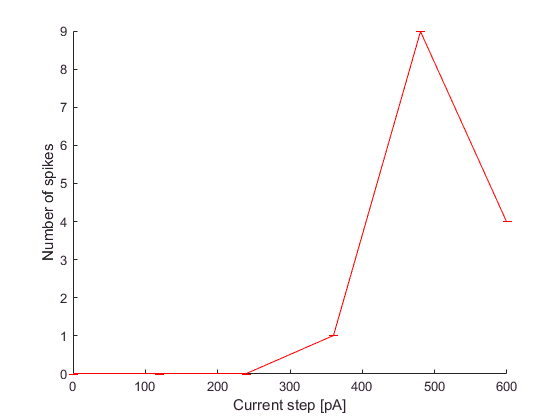

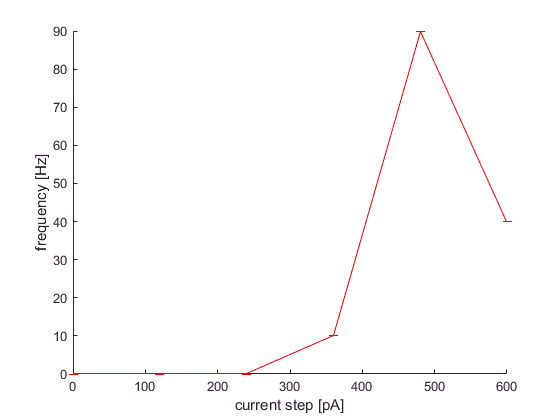

t2n_FIplot('tmpfolder/',neuron,ostruct); % plot an f-i-relationship from the simulation results

rmdir('tmpfolder','s')            % remove the tmpfolder


## Tutorial E - simulation protocol: several voltage clamp steps (I-V relationship)

We now want to use a voltage instead of a current clamp, apply different voltage steps and plot a so called I-V curve.

amp = -140:10:-60;                 % define a series of voltage amplitude steps [mV]
nneuron = cell(numel(amp),1);      % initialize (clear) simulation list

We define the SEClamp electrode and again use the t2n_as function to fill up the rest of the neuron specification. Also, you see here how to record a parameter from a point process (current "i" of the SEClamp electrode in this case): Simply replace the former "cell" field (for cell recordings) with the name of the point process ("SEClamp"). The node definition specifies the node at which the point process is located in this case.

nneuron{1} = neuron;                                                    % use neuron structure defined above as basis for the first simulation instance
nneuron{1}.record{1}.SEClamp = struct('node',1,'record','i');           % record current "i" from SEClamp electrode which will be located at node 1

for n = 1:numel(amp)
    % now define the SEClamp in all simulations (remember that all other parameters were only defined in simulation 1)
    nneuron{n}.pp{1}.SEClamp = struct('node',1,'times',[0 50 150],'amp',[-80 amp(n) -80]);   
end
nneuron = t2n_as(1,nneuron);                                            % then use the previously defined neuron structure as basis for each other simulation

out = t2n(nneuron,tree,'-w-q');                                         % execute t2n

Now we can plot the recorded electrode currents for each voltage step

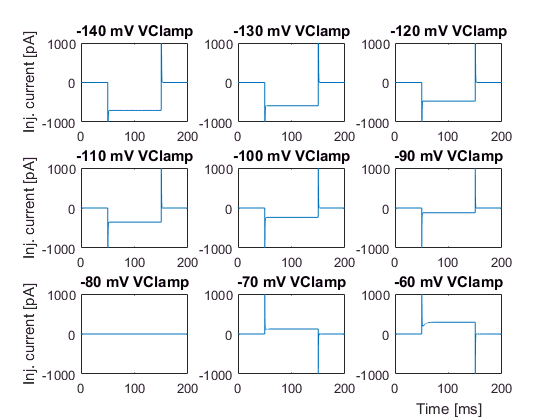

figure;
for n = 1:numel(amp)                                             % go through simulations/amplitudes
    subplot(ceil(sqrt(numel(amp))),ceil(sqrt(numel(amp))),n)     % make subplot for each simulation
    plot(out{n}.t,out{n}.record{1}.SEClamp.i{1}*1000)            % plot time vs current of current simulation
    title(sprintf('%g mV VClamp',amp(n)))                        % add legend
    if rem(n-1,ceil(sqrt(numel(amp))))==0
        ylabel('Inj. current [pA]')
    end
    xlim([0,200])
    ylim([-1000 1000])
end
linkaxes                                                         % make all axes the same size
xlabel('Time [ms]')

Plotting the steady state current during the voltage step against the applied voltage step would give us the I-V relationship. However, again, we can save a lot of typing/formatting, if we use the the t2n functions for running voltage steps and plotting an I-V-relationship:

amp = -140:10:-60;                % specify the same voltage steps [mV] as above
holding_voltage = -80;            % specify the same holding voltage [mV] as above
duration = [50 100 50];           % specify the same injection durations [ms] as above
mkdir('tmpfolder')                % t2n_currSteps saves the result of the simulations 
                                  % which can then be used by various plotting functions
                                  % hence we here specify a temporary folder. this of course
                                  % can also be a permanent folder in your simulations
t2n_VoltSteps(neuron,tree,amp,duration,holding_voltage,'tmpfolder/'); % run the current step simulations and save the results in tmpfolder


Mean Rin in Model(@-90mV) is -181.225 +- 0 MOhm (s.e.m., -10mV)
Mean Rin in Model(@-70mV) is -176.244 +- 0 MOhm (s.e.m., +10mV)

Mean capacitance in Model(@-90mV) is 2379.64 +- 0 pF (s.e.m. -10mV)
Mean capacitance in Model(@-70mV) is 2151.61 +- 0 pF (s.e.m. +10mV)


Conductance at rest: 10.1 nS
Kir Slope Conductance model cells  -0.377+-0 nS, 


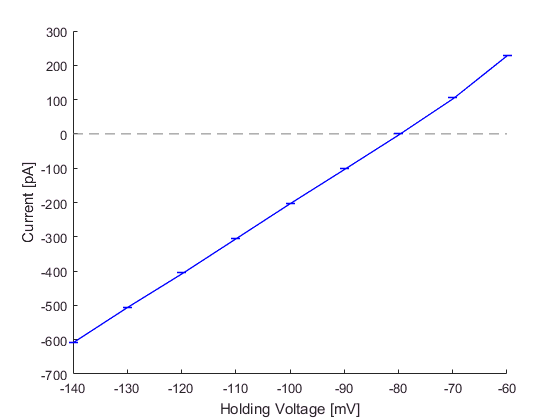

t2n_IVplot('tmpfolder/',neuron,ostruct); % plot an f-i-relationship from the simulation results

rmdir('tmpfolder','s')            % remove the tmpfolder

As you can see, the I-V curve is linear at these hyperpolarized steps, as only the passive channel is conducting there.

## Tutorial F - Map the backpropagating AP onto the tree and plot its distance-dependence

As t2n features the trees toolbox, morphological visualizations are easy. We illustrate this by mapping the membrane potential at specific times during a current injection on our morphology.

nneuron = neuron;                                                         % copy standard neuron structure
nneuron.pp{1}.IClamp = struct('node',1,'times',[50 150],'amp',[0.6 0]);   % define the IClamp
times = [52 53 54 55];                                                    % define some time points at which the voltage should be mapped
nneuron.record{1}.cell.node = 1:numel(tree{1}.X);                         % use already defined recording but modify it to record from all nodes of the tree
warning off 
out = t2n(nneuron,tree,'-w-q');                                    % execute t2n

warning on

The plot_tree function of the TREES toolbox allows handing over a vector  with the same size as the number of nodes which is then mapped on the tree. This means we need to get only one value from each recorded voltage  vector. You can do this by using the Matlab cellfun function, or simply use our t2n_get function which can be used to extract values at a given time (or time span) or to easily apply a function (such as 'mean') on each recorded vector (see documentation of t2n_get).

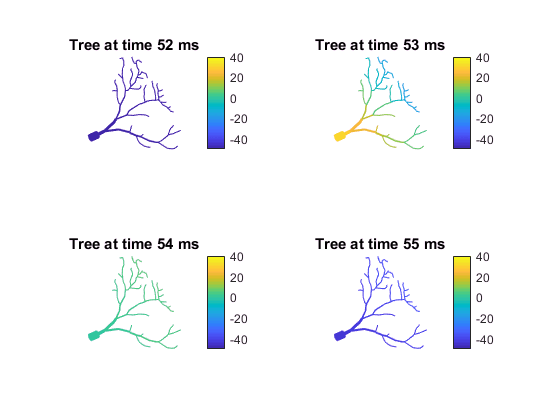

figure;
for tt = 1:numel(times)                                                   % loop through all defined time points
    subplot(ceil(sqrt(numel(times))),ceil(sqrt(numel(times))),tt)         % make quadratically arranged subplots
    vec = t2n_get(out,'v',times(tt));                                     % extract the voltages at that time point
    plot_tree(tree{1},vec{1});                                            % plot the tree with the voltage at that time at each node
    colorbar                                                              % add a colorbar
    set(gca,'CLim',[-50 40])                                              % make the colors go only from -50 to 40 mV
    axis off
    title(sprintf('Tree at time %g ms',times(tt)))
end

Mostly, it is interesting to evaluate the maximal voltage amplitude of such an backpropagating action potential, e.g. its distance-dependence and its delay at each location of the cell. T2n features a "ready-to-use" function to this, which maps the maximal voltage amplitude on the morphology and plots the maximal bAP and the delay at each location versus the distance to the soma:

cstep = 1.3;                      % short current step [nA] to be applied for eliciting the bAP
mkdir('tmpfolder')                % t2n_currSteps saves the result of the simulations 
                                  % which can then be used by various plotting functions
                                  % hence we here specify a temporary folder. this of course
                                  % can also be a permanent folder in your simulations

t2n_bAP(neuron,tree,cstep,'tmpfolder/',0)  % do the simulation

Sim 1: HOC writing time: 0 min 0.07 sec
NEURON execute time: 0 min 0.21 sec
Data loading time: 0 min 0.01 sec
Reached Voltage: -80.0,  of target voltage -85.4 mV
Sim 1: HOC writing time: 0 min 0.05 sec
NEURON execute time: 0 min 0.21 sec
Data loading time: 0 min 0.01 sec
Reached Voltage: -84.2,  of target voltage -85.4 mV
Sim 1: HOC writing time: 0 min 0.04 sec
NEURON execute time: 0 min 0.20 sec
Data loading time: 0 min 0.01 sec
Reached Voltage: -88.4,  of target voltage -85.4 mV
Sim 1: HOC writing time: 0 min 0.03 sec
NEURON execute time: 0 min 0.20 sec
Data loading time: 0 min 0.01 sec
Reached Voltage: -86.3,  of target voltage -85.4 mV
Sim 1: HOC writing time: 0 min 0.04 sec
NEURON execute time: 0 min 0.21 sec
Data loading time: 0 min 0.01 sec
Reached Voltage: -85.2,  of target voltage -85.4 mV


Sim 1: HOC writing time: 0 min 0.07 sec
NEURON execute time: 0 min 0.31 sec
Data loading time: 0 min 0.30 sec


Dendritic Velocity cell 1: 302.286730 µm/ms (time to max amp)
Far Axonal Velocity cell 1: NaN µm/ms (time to half-max amp)
Near Axonal Velocity cell 1: NaN µm/ms (time to half-max amp)
Mean voltage attenuation @ 185 µm: 91.9631 +- 0 % (s.e.m.)
Mean delay @ 185 µm: 0.216402 +- 0 ms (s.e.m.)


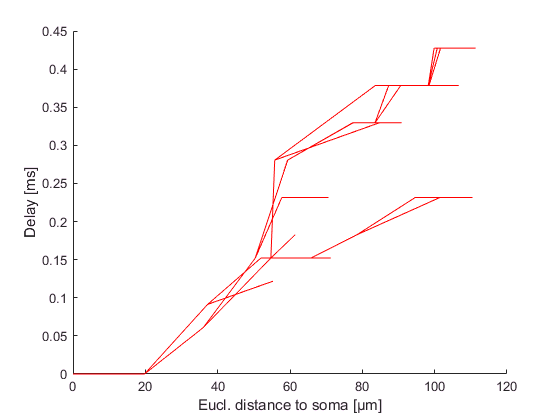

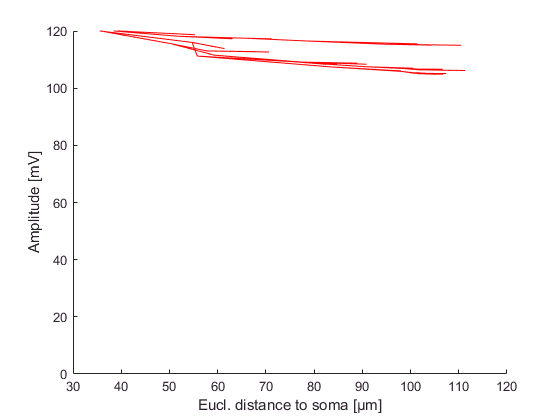

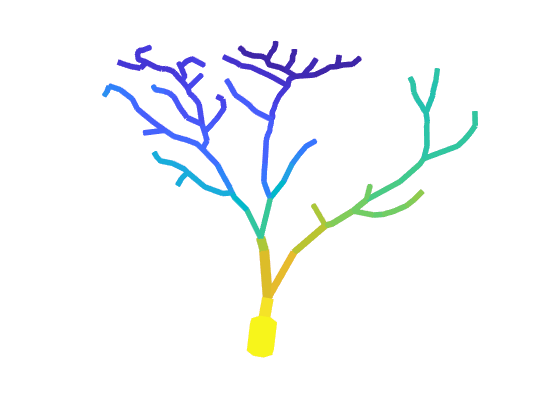


t2n_plotbAP('tmpfolder/',neuron);

rmdir('tmpfolder','s')            % remove the tmpfolder

## Tutorial G - Do a parameter scan or how to modify mechanism parameters

Now we want to analyze the impact of a parameter on spiking, e.g. for optimizing the model. We simply use a for loop to create neuron instances, each being the same except for one parameter that is changed.

fac = 0:0.5:2;                                          % define the multiplication factor range of the parameter scan
nneuron = cell(numel(fac),1);                           %initialize neuron cell array (generally good strategy if you are using this variable in different sections)
for f = 1:numel(fac)                                    % loop through number of different factors
    nneuron{f} = neuron;                                % copy standard neuron definition
    nneuron{f}.mech{1}.soma.hh.gkbar = fac(f) * 0.036;     % change the HH potassium channel density according to fac
end
nneuron{1}.pp{1}.IClamp = struct('node',1,'times',[50 150],'amp',[0.6 0]);    % again define the IClamp only for first instance...
nneuron = t2n_as(1,nneuron);                                                  % ... and let t2n use it for the rest

out = t2n(nneuron,tree,'-w-q');   % execute t2n

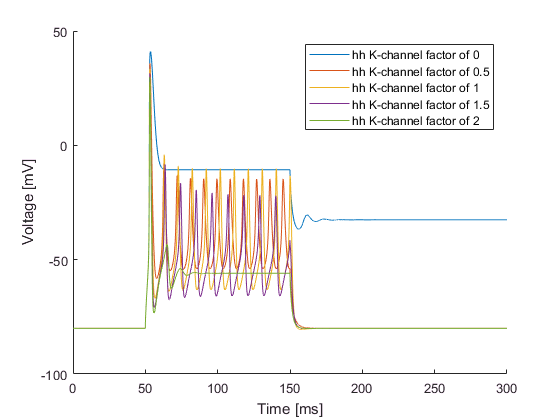


% plot the result
figure; hold all
for f = 1:numel(fac)
    plot(out{f}.t,out{f}.record{1}.cell.v{1})  % plot time vs voltage of each simulation
end
legend(arrayfun(@(x) sprintf('hh K-channel factor of %g',x),fac,'uni',0))   % add legend
xlabel('Time [ms]')
ylabel('Voltage [mV]')

If your model is to complex or you want to write your code more compact, there are two t2n function, which help you manipulating mechanism parameters:

t2n_blockchannel can be used to decrease the maximal conductance of any channel by a certain amount. E.g.

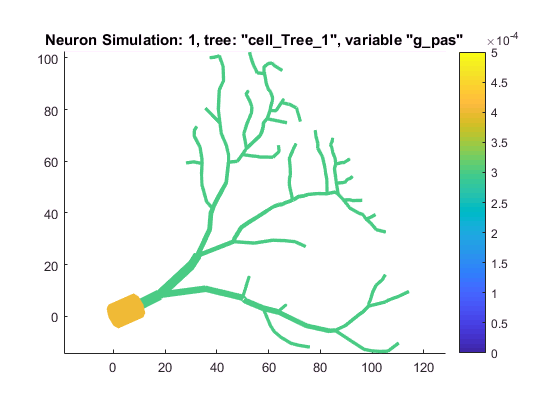

t2n_getMech(neuron,tree,'g_pas'), set(gca,'CLim',[0 0.0005]),colorbar

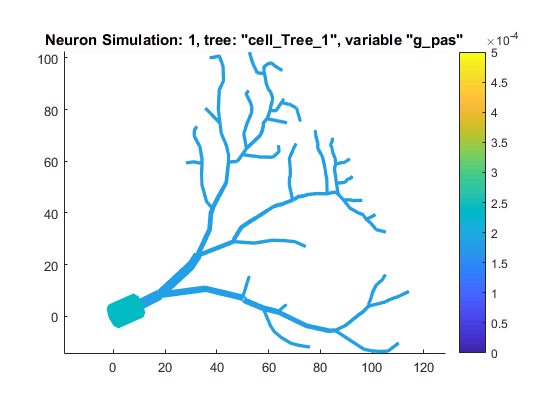

nneuron = t2n_blockchannel(neuron,{'hh','pas'},40);
t2n_getMech(nneuron,tree,'g_pas'), set(gca,'CLim',[0 0.0005]),colorbar

decreases the maximal conductances of the hh and the passive mechanism by 40 %. 

This function can even applied in a region-specific way by using the third input of it. E.g.

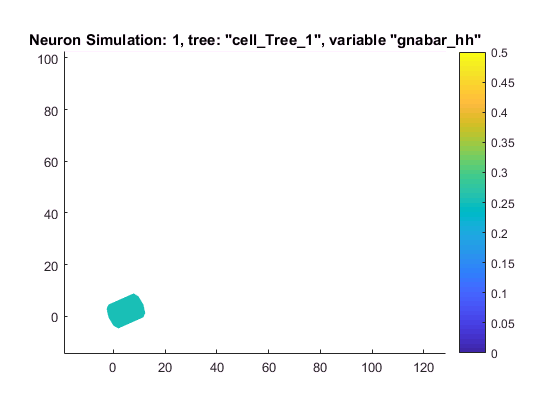

t2n_getMech(neuron,tree,'gnabar_hh'), set(gca,'CLim',[0 0.5]),colorbar

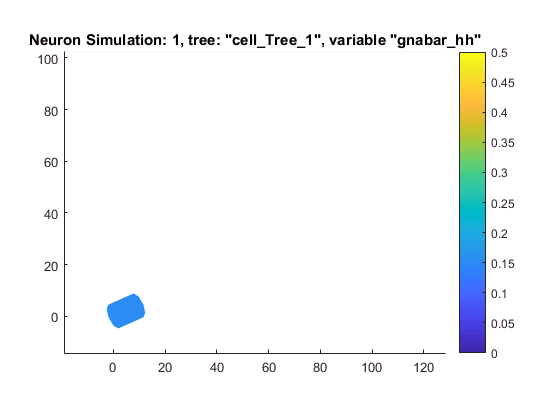

nneuron = t2n_blockchannel(neuron,'hh',40,'soma');
t2n_getMech(nneuron,tree,'gnabar_hh'), set(gca,'CLim',[0 0.5]),colorbar

reduces only the somatic hh conductance by 40 % (which in this example would not make a difference as hh is only defined in the soma anyways).

You can even use this function to increase the conductance by using negative values. E.g.

nneuron = t2n_blockchannel(neuron,'hh',-200,'soma');

increases the conductance by 200 % (i.e. a factor of 3).

Important note: The function assumes that maximal conductance parameters have the 'bar' in their names, such as gbar or gkbar. It changes all conductances of one mechanism, so in the case of hh it changes gnabar, gkbar but not gl. If you want a specific conductance to be modified, use the 4th input to t2n_blockchannel, e.g.

nneuron = t2n_blockchannel(neuron,'hh',40,[],'gbar');

If you want to change more parameters than just the conductance you can use t2n_changemech. You can specify the change in relative values:

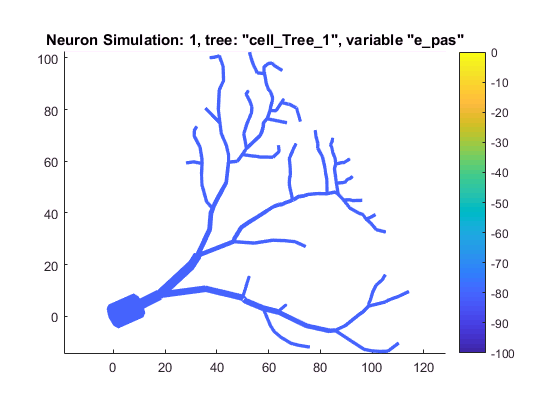

t2n_getMech(neuron,tree,'e_pas'), set(gca,'CLim',[-100 0]),colorbar

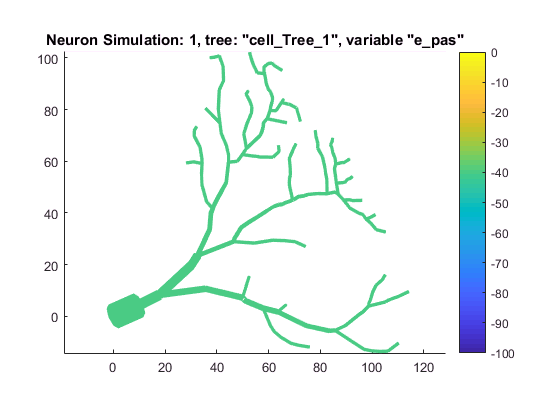

nneuron = t2n_changemech(neuron,struct('e_pas', 0.5));
t2n_getMech(nneuron,tree,'e_pas'), set(gca,'CLim',[-100 0]),colorbar

reduces the equlibrium potential of the passive channel everywhere by a factor of 50%.

On the other side

t2n_getMech(neuron,tree,'e_pas'), set(gca,'CLim',[-100 0]),colorbar

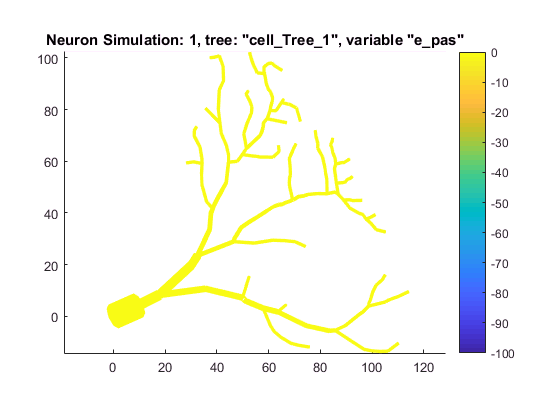

nneuron = t2n_changemech(neuron,struct('e_pas', 0.5),'absolute');
t2n_getMech(nneuron,tree,'e_pas'), set(gca,'CLim',[-100 0]),colorbar

changes the passive equilibrium potential everywhere to 0.5 mV.

## Tutorial H - Synaptic stimulation, simple Alpha synapse

Now we come closer to the point of building networks. First we do a synaptic stimulation of a chosen point within the morphology using the NEURON AlphaSynapse point process which adds synaptic current at a specific time "onset" at the location it is placed. For this example, we chose the most far away point in the tree as the synapse location, which can be found by using the TREES toolbox function Pvec_tree. Other examples to extract a specific synapse location that can be tested here is: searching for termination points with "find(T_tree(tree{1})"; getting nodes at a specific distance to the soma with "find(plen == x)" (or add some tolerance y: "find(plen-x < y)"); getting nodes of a specific region name REG with "find(tree{1}.R == find(strcmp(tree{1}.rnames,REG))" or any combinaton of them.

nneuron = neuron;                                                         % copy standard neuron structure
plen = Pvec_tree(tree{1});                                                % get path length to soma at each node of morphology
[~,synIDs] = max(plen);                                                   % search for the most far away point in the morpholgy    
nneuron.pp{1}.AlphaSynapse = struct('node',synIDs,'gmax',0.01,'onset',20);% add an AlphaSynapse at this location
nneuron.record{1}.cell.node = cat(1,1,synIDs);                            % record somatic voltage and voltage at synapse
nneuron.record{1}.AlphaSynapse = struct('node',synIDs,'record','i');      % record synaptic current

out = t2n(nneuron,tree,'-w-q');              % execute t2n

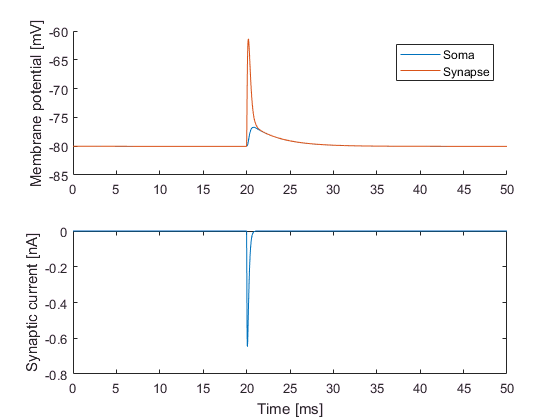


% plot the result (Vmem at soma and synapse and synaptic current)
figure;
subplot(2,1,1)
hold all
plot(out.t,out.record{1}.cell.v{1})                 % plot time vs voltage at soma
plot(out.t,out.record{1}.cell.v{synIDs})            % plot time vs voltage at dendrite end
legend('Soma','Synapse')
ylabel('Membrane potential [mV]')
ylim([-85,-60])
xlim([0,50])
subplot(2,1,2)
plot(out.t,out.record{1}.AlphaSynapse.i{synIDs})    % plot time vs synaptic current
xlim([0,50])
ylabel('Synaptic current [nA]')
xlabel('Time [ms]')

## Tutorial I - Synaptic stimulation, Exp2Syn synapse and a NetStim

A more customizable synapse in NEURON is the Exp2Syn point process as it is activated by another cell or point process. Hence, if we use such a synapse, we have to make use of NEURON NetCon objects, which can be defined in the .con field of the neuron structure. Additionally, we have to introduce some cell that stimulates the synapse at given times, for which we will introduce a NetStim as an artificial cell. This cell, as all real and artificial cells, has to be defined in the tree structure and is quite simple to define:

trees = {};
trees{1} = tree{1};
trees{2} = struct('artificial','NetStim','start',10,'interval',15,'number',10); % add a NetStim as an artificial cell and define the start (10 ms) the interval (15 ms) and the number (10) of spikings
trees = t2n_writeTrees(trees,[],fullfile(pwd,'test.mtr'));                                    % tree morphologies are rewritten because this NetStim might be not written yet

Tree hoc writing time: 0 min 0.63 sec



nneuron = neuron;                                                         % copy standard neuron structure
plen = Pvec_tree(trees{1});                                                % get path length to soma at each node of morphology
[~,synIDs] = max(plen);                                                   % search for the most far away point in the morpholgy    
nneuron.pp{1}.Exp2Syn = struct('node',synIDs,'tau1',0.2,'tau2',2.5,'e',0);% add an Exp2Syn at this location with 0.2 ms rise and 2.5 ms decay time
nneuron.record{1}.cell.node = cat(1,1,synIDs);                            % record somatic voltage and voltage at synapse
nneuron.record{1}.Exp2Syn = struct('node',synIDs,'record','i');           % record synaptic current
nneuron.con(1) = struct('source',struct('cell',2),'target',struct('cell',1,'pp','Exp2Syn','node',synIDs),'delay',0,'threshold',0.5,'weight',0.1);  % connect the NetStim (cell 2) with the target (point process Exp2Syn of cell 1 at node specified in synIDs), and add threshold/weight and delay of the connection (NetStim parameters)

out = t2n(nneuron,trees,'-w-q');                                    % execute t2n

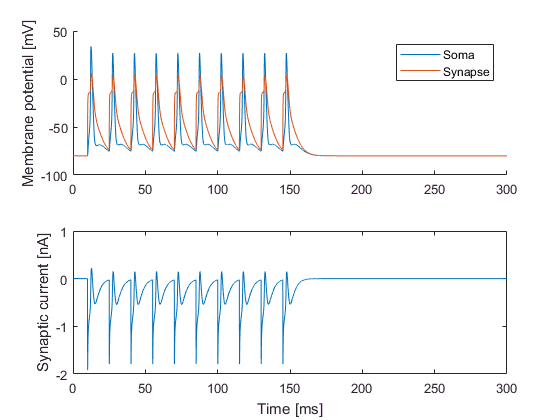


% plot the result (Vmem at soma and synapse and synaptic current)
figure;
subplot(2,1,1)
hold all
plot(out.t,out.record{1}.cell.v{1})       % plot time vs voltage at soma
plot(out.t,out.record{1}.cell.v{synIDs})  % plot time vs voltage at dendrite end
legend('Soma','Synapse')
ylabel('Membrane potential [mV]')
subplot(2,1,2)
plot(out.t,out.record{1}.Exp2Syn.i{synIDs})  % plot time vs synaptic current
ylabel('Synaptic current [nA]')
xlabel('Time [ms]')

## Tutorial J - Small network with Poissonian input

Our last tutorial gives an example of how to create a small network that comprises feed-forward inhibition. We use the definitions of the previous tutorial and add an inhibitory integrate-and-fire point neuron that receives input from our excitatory cell and and returns somatic inhibition. Furthermore, we now do not use a NetStim but a VecStim, which allows us to specify a 50 Hz Poissonian spike pattern that was generated with t2n_poissonSpikeGen. Last, we added a line that would transform the feed-forward inhibition to a feed-back inhibition network by changing the input of the inhibitory neuron from the netstim to the real cell.

To speed up simulation time we furthermore enable the parallel Neuron feature (cells are distributed onto different cores) + variable time step, by setting nneuron.params.parallel to 4 cores and nneuron.params.cvode to 1. This feature becomes more powerful if the more cells are used in the network and the more cores are available to be used by T2N.

trees = {};
trees{1} = tree{1};
trees{2} = struct('artificial','VecStim');                             % add a VecStim as an artificial cell. This class can have a vector played to it defining its activity
trees{3} = struct('artificial','IntFire2','taus',15); % add a IntFire2 as an artificial cell and define its tau decay time
trees = t2n_writeTrees(trees,[],fullfile(pwd,'test.mtr'));                                    % tree morphologies are rewritten because this NetStim might be not written yet

Tree hoc writing time: 0 min 0.22 sec



nneuron = neuron;                                                         % copy standard neuron structure
nneuron.params.parallel = 4;                                              % enable parallel Neuron and set the number of used cores to 4
nneuron.params.cvode = 1;                                                 % enable the variable time step method to fully profit from parallel Neuron (be reminded that out.t is a cell then, as time steps can be different between cells)
plen = Pvec_tree(trees{1});                                                % get path length to soma at each node of morphology
[~,synIDsExc] = max(plen);                                                % search for the most far away point in the morpholgy    
nneuron.pp{1}.Exp2Syn(1) = struct('node',synIDsExc,'tau1',0.2,'tau2',2.5,'e',0);% add an Exp2Syn at this location with 0.2 ms rise and 2.5 ms decay time
synIDsInh = 1;                                                            % choose root as point of inhibitory synapse
nneuron.pp{1}.Exp2Syn(2) = struct('node',synIDsInh,'tau1',0.5,'tau2',5,'e',-80);% add an inhibitory (e=-80) Exp2Syn at this location with 0.2 ms rise and 2.5 ms decay time
nneuron.record{1}.cell.node = cat(1,1,synIDsExc);                         % record somatic voltage and voltage at synapse
nneuron.record{1}.Exp2Syn(1) = struct('node',synIDsExc,'record','i');        % record synaptic current
nneuron.record{1}.Exp2Syn(2) = struct('node',synIDsInh,'record','i');        % record synaptic current
nneuron.con(1) = struct('source',struct('cell',2),'target',struct('cell',1,'pp','Exp2Syn','node',synIDsExc),'delay',0.1,'threshold',0.5,'weight',0.1);  % connect the NetStim (cell 2) with the target (point process Exp2Syn of cell 1 at node specified in synIDsExc), and add threshold/weight and delay of the connection (NetStim parameters)
nneuron.con(2) = struct('source',struct('cell',2),'target',struct('cell',3),'delay',0.1,'threshold',0.5,'weight',1);  % connect the NetStim (cell 2) with the inhibitory cell to create a feed-forward inhibitory loop, and add threshold/weight and delay of the connection (NetStim parameters)
% nneuron.con(2) = struct('source',struct('cell',1,'node',1),'target',struct('cell',3),'delay',0,'threshold',0.5,'weight',1);  % connect the real cell with the inhibitory cell to create a feed-back inhibitory loop, and add threshold/weight and delay of the connection (NetStim parameters)
nneuron.con(3) = struct('source',struct('cell',3),'target',struct('cell',1,'pp','Exp2Syn','node',synIDsInh),'delay',3,'threshold',0.5,'weight',0.3);  % connect the inhibitory cell with the target (point process Exp2Syn of cell 1 at node specified in synIDsInh), and add threshold/weight and delay of the connection (NetStim parameters)

[spikeMat,tvec] = t2n_poissonSpikeGen(50,neuron.params);                     % generate a 50 Hz Poissonian spike distribution
nneuron.play{2}.cell =  struct('node',1,'play','spike','times',tvec(spikeMat));   % play this spike vector to the VecStim

out = t2n(nneuron,trees,'-w-q');                                    % execute t2n

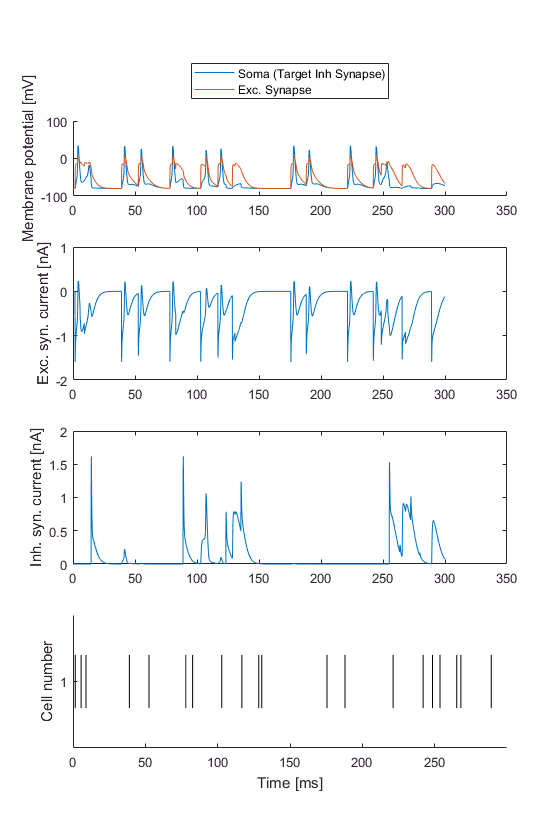


% plot the result (Vmem at soma and synapse and synaptic current)
fig = figure;
subplot(4,1,1)
hold all
plot(out.t{1},out.record{1}.cell.v{1})       % plot time vs voltage at soma
plot(out.t{1},out.record{1}.cell.v{synIDsExc})  % plot time vs voltage at dendrite end
legend('Soma (Target Inh Synapse)','Exc. Synapse','Location','northoutside')
ylabel('Membrane potential [mV]')
subplot(4,1,2)
plot(out.t{1},out.record{1}.Exp2Syn.i{synIDsExc})  % plot time vs synaptic current
ylabel('Exc. syn. current [nA]')
subplot(4,1,3)
plot(out.t{1},out.record{1}.Exp2Syn.i{synIDsInh})  % plot time vs synaptic current
ylabel('Inh. syn. current [nA]')
subplot(4,1,4)
t2n_plotRaster(spikeMat,tvec)
fig.Position(4) = fig.Position(4) * 2;